# ECR-III targeting of the Lorenz system

This walkthrough builds the **Extended Control Regions** controller of

S. Iplikci and Y. Denizhan, *An improved neural network based targeting method for chaotic dynamics*, Chaos Solitons & Fractals **17** (2003) 523-529,

step by step, on the Lorenz system, and measures what it buys you.

The idea in one paragraph. Chaos control of the OGY family can only act once the trajectory happens to wander into a small region around the target orbit, and waiting for that costs time. ECR **targets**: it learns, from input/output data alone, which states can be pushed into that region in one step, which states can be pushed into **those** in one step, and so on. Those nested sets are the control regions $T_0, T_1, \ldots, T_K$. ECR-III adds two things to its predecessor: each region is split into clusters, and each cluster gets its own small RBF network, so the region of the current state can be found analytically from a distance rather than by trying every network in turn.

Nothing below uses the Lorenz equations for control. The equations are only used to **run the experiment**; the controller sees measurements and nothing else.

Run time is a few minutes. Run `startup_ecr` once before this script.

startup_ecr

ECR-III toolbox on path (C:\Users\npcoz\OneDrive - Imperial College London\Project\Codes\ECR_III_MATLAB)


## 1. Plant, target, and the admissible parameter set

The Lorenz flow


$$\dot x = \sigma (y - x), \qquad \dot y = \rho x - y - x z, \qquad \dot z =
 x y - \beta z$$


is turned into the discrete map of Eq. (1),


$$\mathbf{z}_{n+1} = \mathbf{G}(\mathbf{z}_n, \mathbf{p}_n),$$


by observing it on the Poincare surface of section $y = y_{PSS} = 8.4853$, so the observed state is $\mathbf{z} = [x\;\; z]^T$ at successive crossings. The control parameters are $\mathbf{p} = [\sigma\;\; \rho\;\; \beta]^T$, and each of them may move inside the allowable set of Eq. (3),


$$\Pi = \{ p^i : p^i_{nom} - \delta p^i_{max} < p^i < p^i_{nom} + \delta
 p^i_{max} \}.$$


The target $\mathbf{z}^*$ is the period-1 unstable orbit of the flow; the code finds it by Newton iteration on the Poincare map, which is where the value quoted in Table 2 of the paper comes from.

S = sys_lorenz_real();

fprintf('target      z* = [%.4f %.4f]   (paper: [14.2387 39.7934])\n', S.zstar);

target      z* = [14.2522 39.7867]   (paper: [14.2387 39.7934])


fprintf('nominal      p = [%.3f %.3f %.3f]\n', S.pnom);

nominal      p = [10.000 28.000 2.667]


fprintf('allowed  dp_max = [%.3f %.3f %.3f]\n', S.dpmax);

allowed  dp_max = [0.300 0.840 0.080]


fprintf('target region radius delta = %.2f\n', S.delta);

target region radius delta = 0.30


How unstable is the target? The eigenvalues of the Poincare map linearised at $\mathbf{z}^*$ tell us what the controller is up against.

h = 1e-4;  J = zeros(2);
for j = 1:2
    dz = zeros(2,1);  dz(j) = h;
    [~, Pp] = S.step(S.hfromz(S.zstar + dz), S.pnom);
    [~, Pm] = S.step(S.hfromz(S.zstar - dz), S.pnom);
    J(:,j) = (Pp - Pm)/(2*h);
end
fprintf('eigenvalues of dG/dz at z*: %s\n', mat2str(eig(J).', 4));

eigenvalues of dG/dz at z*: [2.313e-09 4.713]


## 2. The experiment: random parameters inside Pi

The only data the method ever gets are triples $(\mathbf{z}_n, \mathbf{p}_n, \mathbf{z}_{n+1})$ collected while a parameter vector drawn uniformly from $\Pi$ is applied at every step. That is a deliberately dumb experiment - it is exactly what you could do on a rig.

opt          = ecr_default_options();
opt.nData    = 4000;      % raw triples; the demos use 6000
opt.trajLen  = 25;
opt.Kmax     = 4;         % T_1 ... T_4
opt.nTrials  = 60;        % initial conditions for the reaching-time test
opt.maxSteps = 150;
opt.seed     = 1;

D = ecr_cache_data(S, opt);      % cached in results/, delete to regenerate

[data] reusing C:\Users\npcoz\OneDrive - Imperial College London\Project\Codes\ECR_III_MATLAB\results\data_lorenz_real.mat (6800 triples)


Where does that data live? The Lorenz attractor, seen on this section, is almost a curve: the map contracts so hard in one direction that the useful dynamics is effectively one-dimensional. The black circle is the target region $S_0$, the set the controller is trying to reach.

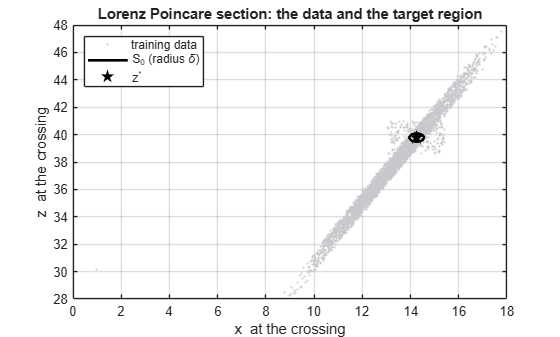

col = ecr_palette(6);
figure('Color','w');
plot(D.Z(1,:), D.Z(2,:), '.', 'Color', [0.78 0.78 0.80], 'MarkerSize', 4);
hold on
th = linspace(0, 2*pi, 200);
plot(S.zstar(1) + S.delta*cos(th), S.zstar(2) + S.delta*sin(th), 'k-', ...
     'LineWidth', 2);
plot(S.zstar(1), S.zstar(2), 'kp', 'MarkerFaceColor', 'k', 'MarkerSize', 10);
xlabel('x  at the crossing');  ylabel('z  at the crossing');
title('Lorenz Poincare section: the data and the target region');
legend({'training data', 'S_0 (radius \delta)', 'z^*'}, 'Location', 'northwest');
grid on;  box on
hold off

## 3. Definition 1: the target region T_0

A state belongs to $S_0 = T_0$ if it is inside the $\delta$-ball **and** some admissible parameter keeps it there for one step (Eq. 4):


$$\|\mathbf{z}_n - \mathbf{z}^*\| < \delta \quad \mathrm{and} \quad
 \|\mathbf{G}(\mathbf{z}_n,\mathbf{p}) - \mathbf{z}^*\| < \delta, \;\;
 \mathbf{p} \in \Pi .$$


In the data, the parameter that was actually applied is the evidence that such a $\mathbf{p}$ exists - and it becomes the training target of the network $NN_0$, which is the local controller.

M   = size(D.Z,2);
dz  = sqrt(sum((D.Z  - repmat(S.zstar,1,M)).^2, 1));
dzn = sqrt(sum((D.Zn - repmat(S.zstar,1,M)).^2, 1));
fprintf('%d triples, %d start inside the delta-ball, %d of those stay in it\n', ...
        M, sum(dz < S.delta), sum(dz < S.delta & dzn < S.delta));

6800 triples, 875 start inside the delta-ball, 54 of those stay in it


## 4. Definition 3: the outer regions, extracted with the networks themselves

$\mathbf{z}_n \in T_i$ when it is **not** in $T_0 \ldots T_{i-1}$ and its successor is in $T_{i-1}$ (Eq. 7). Membership of the successor is decided by the already trained level $i-1$ model: feed the state to it and accept it if the parameter it returns lies inside $\Pi$. That is the data-extraction procedure of Fig. 3 - the system equations are never consulted.

`ecr_train` does exactly this loop, clustering each region and fitting one RBF network per cluster.

m3 = ecr_train(S, D, opt, 'ECR-III');

[train ECR-III] T0: 54 points, 1 cluster(s), claims 832 states
[train ECR-III] T1: 224 points, 2 cluster(s), r = 1.736, claimed total 4994/6800
[train ECR-III] T2: 600 points, 3 cluster(s), r = 1.469, claimed total 5920/6800
[train ECR-III] T3: 281 points, 1 cluster(s), r = 4.826, claimed total 6260/6800
[train ECR-III] T4: 156 points, 1 cluster(s), r = 6.28, claimed total 6438/6800
[train ECR-III] 5 regions, 8 networks, 0.8 s


m2 = ecr_train(S, D, opt, 'ECR-II');    % one network per region, for comparison

[train ECR-II] T0: 54 points, 1 cluster(s), claims 799 states
[train ECR-II] T1: 208 points, 1 cluster(s), r = NaN, claimed total 5475/6800
[train ECR-II] T2: 488 points, 1 cluster(s), r = NaN, claimed total 6056/6800
[train ECR-II] T3: 234 points, 1 cluster(s), r = NaN, claimed total 6332/6800
[train ECR-II] T4: 127 points, 1 cluster(s), r = NaN, claimed total 6475/6800
[train ECR-II] 5 regions, 5 networks, 0.1 s


ecr_summary(m3)

ECR-III model for "lorenz_real"
  target z*      : [14.2522 39.7867]
  delta          : 0.3
  regions        : 5 (T0 ... T4)
  networks       : 8
  training time  : 0.84 s
  ------------------------------------------------------------
   region   points   radius r   clusters   cluster sizes / RMSE
   T0          25    0.02281          1   [25] / [0.321]
   T1         224      1.736          2   [90 134] / [0.385 0.476]
   T2         600      1.469          3   [17 375 208] / [0.362 0.528 0.519]
   T3         281      4.826          1   [281] / [0.553]
   T4         156       6.28          1   [156] / [0.534]


## 5. The clustering radius

Section 3.3 picks the radius $r$ as "the first minimum of the histogram of the inter-data distances by visual analysis", then puts any two points closer than $r$ in the same cluster. `ecr_choose_radius` automates the choice and keeps the histogram so you can still check it by eye - which is what the paper actually prescribes.

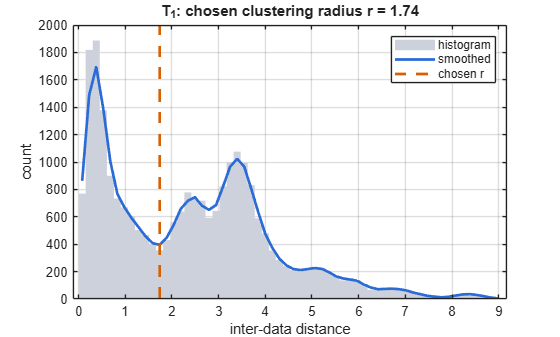

L = m3.levels(2);                       % the region T_1
figure('Color','w');
bar(L.radiusInfo.centers, L.radiusInfo.counts, 1, 'FaceColor', [0.80 0.82 0.86], ...
    'EdgeColor', 'none');
hold on
plot(L.radiusInfo.centers, L.radiusInfo.smooth, '-', 'Color', col(1,:), 'LineWidth', 2);
yl = ylim;
plot([L.radius L.radius], yl, '--', 'Color', col(2,:), 'LineWidth', 2);
xlabel('inter-data distance');  ylabel('count');
title(sprintf('T_1: chosen clustering radius r = %.3g', L.radius));
legend({'histogram', 'smoothed', 'chosen r'}, 'Location', 'northeast');
grid on;  box on
hold off

## 6. Equation (8): which cluster is the state in?

Each cluster $C_{ij}$ is summarised by its mean $\mu_{ij}$ and a normalised covariance $\underline{N}_{ij}$, and the region of a state follows from the Normalised Mahalanobis Distance


$$\mathrm{NMD}_{ij}^2(\mathbf{z}_n) = (\mathbf{z}_n - \mu_{ij})^T
 \underline{N}_{ij} (\mathbf{z}_n - \mu_{ij}).$$


The smallest NMD wins and its network $NN_{ij}$ is activated. The ellipses below are the 2-sigma contours of those clusters, coloured by control region: $T_1$ hugs the target, and the higher regions reach further out along the attractor - which is precisely the "extension" of the activation region that gives the method its name.

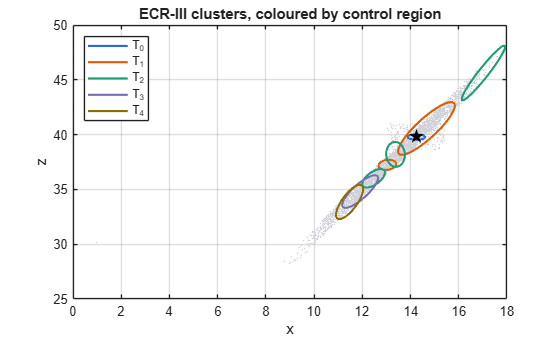

figure('Color','w');
plot(D.Z(1,:), D.Z(2,:), '.', 'Color', [0.82 0.82 0.85], 'MarkerSize', 3);
hold on
hs = {};  lb = {};
for k = 1:numel(m3.levels)
    Lk = m3.levels(k);
    for j = 1:numel(Lk.CL)
        mu = Lk.CL(j).mu;
        [V, Dg] = eig((Lk.CL(j).Sigma + Lk.CL(j).Sigma')/2);
        d = sqrt(max(diag(Dg), 0));
        t = linspace(0, 2*pi, 100);
        E = repmat(mu,1,numel(t)) + 2*V*[d(1)*cos(t); d(2)*sin(t)];
        hp = plot(E(1,:), E(2,:), '-', 'Color', col(k,:), 'LineWidth', 1.6);
        if j == 1
            hs{end+1} = hp; %#ok<SAGROW>
            lb{end+1} = sprintf('T_%d', Lk.index); %#ok<SAGROW>
        end
    end
end
plot(S.zstar(1), S.zstar(2), 'kp', 'MarkerFaceColor', 'k', 'MarkerSize', 10);
xlabel('x');  ylabel('z');
title('ECR-III clusters, coloured by control region');
legend([hs{:}], lb, 'Location', 'northwest');
grid on;  box on
hold off

## 7. The networks

Every cluster carries one Gaussian RBF network mapping the state to the normalised parameter perturbation $\delta \mathbf{p}/\delta \mathbf{p}_{max}$, so "the parameter is inside $\Pi$" is simply "every output is within $\pm 1$". Centres come from k-means, widths from the distance to neighbouring centres, and the output weights from regularised least squares - a closed form, which is why ECR trains in seconds.

net = m3.levels(2).nets{1};
fprintf('NN_1,1: %d inputs, %d centres, %d outputs, %d training points\n', ...
        net.d, size(net.C,2), net.q, net.n);

NN_1,1: 2 inputs, 20 centres, 3 outputs, 90 training points


## 8. The control loop

On line (Fig. 4 of the paper) the loop is: measure the state, find the cluster with the smallest NMD, evaluate its network, apply the parameter if it is admissible, otherwise leave the parameters nominal. The first panel below shows the distance to the target collapsing below $\delta$; the second shows how little the parameters actually have to move; the third shows which region was active at each step.

ecr_seed(7);
h0 = S.init(1);
R  = ecr_simulate(S, @(z) ecr_control(m3, z), h0, opt);
R0 = ecr_simulate(S, [], h0, opt);
fprintf('ECR-III reached S_0 in %d steps; uncontrolled, the same initial\n', R.reach);

ECR-III reached S_0 in 17 steps; uncontrolled, the same initial


fprintf('condition needed %d steps.\n', R0.reach);

condition needed 29 steps.


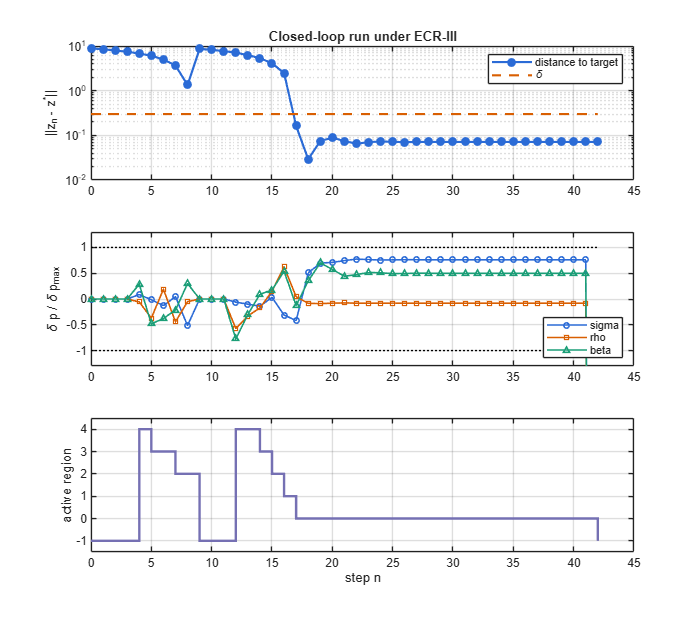

n = size(R.Z,2);
d = sqrt(sum((R.Z - repmat(S.zstar,1,n)).^2, 1));

figure('Color','w', 'Position', [100 100 700 620]);

subplot(3,1,1);
semilogy(0:n-1, max(d,1e-12), 'o-', 'Color', col(1,:), 'LineWidth', 1.6, ...
         'MarkerSize', 5, 'MarkerFaceColor', col(1,:));
hold on
semilogy([0 n-1], S.delta*[1 1], '--', 'Color', col(2,:), 'LineWidth', 1.6);
ylabel('||z_n - z^*||');
title('Closed-loop run under ECR-III');
legend({'distance to target', '\delta'}, 'Location', 'northeast');
grid on;  hold off

subplot(3,1,2);
dp = (R.P - repmat(S.pnom,1,n)) ./ repmat(S.dpmax,1,n);
plot(0:n-1, dp(1,:), 'o-', 'Color', col(1,:), 'LineWidth', 1.2, 'MarkerSize', 4);
hold on
plot(0:n-1, dp(2,:), 's-', 'Color', col(2,:), 'LineWidth', 1.2, 'MarkerSize', 4);
plot(0:n-1, dp(3,:), '^-', 'Color', col(3,:), 'LineWidth', 1.2, 'MarkerSize', 4);
plot([0 n-1], [1 1], 'k:', [0 n-1], [-1 -1], 'k:');
ylim([-1.3 1.3]);  ylabel('\delta p / \delta p_{max}');
legend(S.pnames, 'Location', 'southeast');
grid on;  hold off

subplot(3,1,3);
stairs(0:n-1, R.reg, 'Color', col(4,:), 'LineWidth', 1.8);
ylim([-1.5 max(2, max(R.reg) + 0.5)]);
ylabel('active region');  xlabel('step n');
grid on

## 9.  Average reaching time

The figure of merit of the paper (Section 4) is the average number of steps needed to enter the target region, from many initial conditions. The same initial conditions are used for all three controllers, so the comparison is like for like.

ecr_seed(opt.seed + 100);
H0 = S.init(opt.nTrials);

b0 = ecr_reaching_time(S, [],                      opt, H0);
b2 = ecr_reaching_time(S, @(Z) ecr_control(m2, Z), opt, H0);
b3 = ecr_reaching_time(S, @(Z) ecr_control(m3, Z), opt, H0);

fprintf('no targeting : %6.2f steps (paper, OGY column: 15.09)\n', b0.meanCens);

no targeting :  23.97 steps (paper, OGY column: 15.09)


fprintf('ECR-II       : %6.2f steps (paper: 5.9 - 6.7)\n', b2.meanCens);

ECR-II       :   5.13 steps (paper: 5.9 - 6.7)


fprintf('ECR-III      : %6.2f steps (paper: 6.4 - 6.8)\n', b3.meanCens);

ECR-III      :   6.95 steps (paper: 6.4 - 6.8)


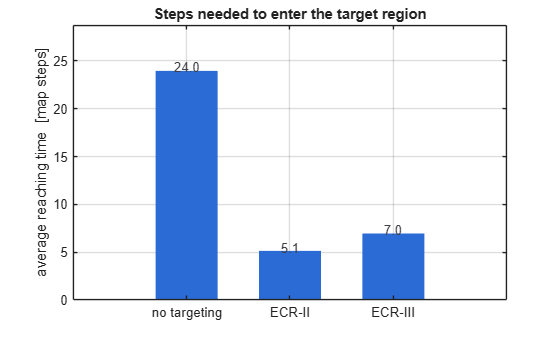

vals = [b0.meanCens, b2.meanCens, b3.meanCens];
figure('Color','w');
hb = bar(vals, 0.6, 'FaceColor', col(1,:), 'EdgeColor', 'none');
hold on
for k = 1:3
    text(k, vals(k) + 0.35, sprintf('%.1f', vals(k)), ...
         'HorizontalAlignment', 'center', 'Color', [0.25 0.25 0.28]);
end
set(gca, 'XTickLabel', {'no targeting', 'ECR-II', 'ECR-III'});
ylabel('average reaching time  [map steps]');
title('Steps needed to enter the target region');
ylim([0 max(vals)*1.2]);
grid on;  box on
hold off

Two numbers worth keeping in view besides the reaching time: the **capture rate** (did the trajectory ever get there) and the **retention** (does the local controller hold it once captured).

fprintf('           capture   retention\n');

           capture   retention


fprintf('ECR-II   :  %5.2f      %5.2f\n', b2.success, b2.hold);

ECR-II   :   1.00       1.00


fprintf('ECR-III  :  %5.2f      %5.2f\n', b3.success, b3.hold);

ECR-III  :   1.00       0.99
